addpath(genpath('./pandemic_model'));
addpath(genpath('./yaml'));

config = yaml.loadFile("./config/job_configs/job_template.yaml");

parametrized_dist = load_arrival_dist("./pandemic-loss-modeling/output/distributions/marani_inspired.yaml");
empirical_dist = load_arrival_dist("./pandemic-loss-modeling/exceedance_results/madhav_original.csv");

empirical_severities = empirical_dist.get_severity(unifrnd(0, 1, 100));
parametrized_severities = parametrized_dist.get_severity(unifrnd(0, 1, 100));

% Check half of COVID exceedance prob in marani distribution
marani_params = struct('sigma', 0.0113, 'theta', 10^-3, 'k', 1.41);
marani_dist = ParametrizedArrivalDist('GeneralizedPareto', 0.62, 10^-3, 1000, marani_params);

function prob = pareto_internal(x, sigma, theta, k)
    prob = (1 + (k/sigma)*(x - theta))^(-1/k);
end

((13 + 7 * (1 - ((1-0.62)*pareto_internal(0.16, 0.0113, 10^-3, 1.41))))/20)

ans = 0.9846

0.9 + (0.1 * parametrized_dist.pd.cdf(4.59))

ans = 0.9596

Examine consequences of interpolation methods

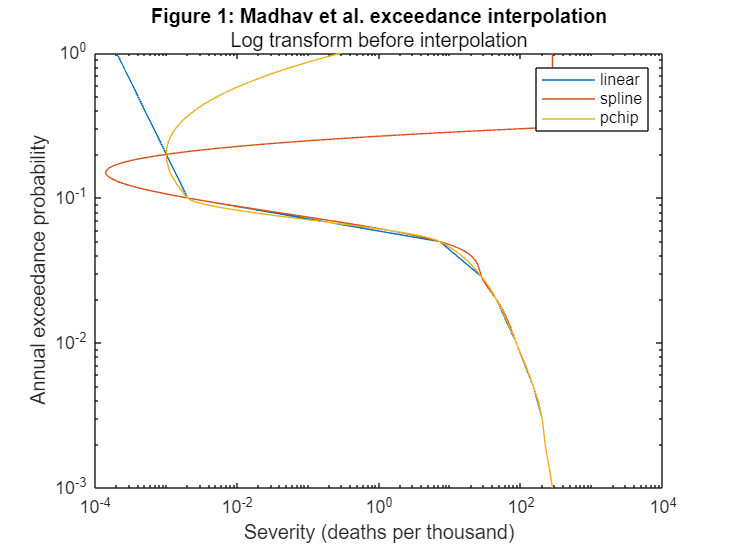

probs = 0:0.001:1;
dist_sample_points = "./pandemic-loss-modeling/exceedance_results/madhav_original.csv";
linear = load_arrival_dist(dist_sample_points, "linear", true);
spline = load_arrival_dist(dist_sample_points, "spline", true);
pchip = load_arrival_dist(dist_sample_points, "pchip", true);

Ys = [linear.get_severity(probs); 
      spline.get_severity(probs);
      pchip.get_severity(probs)];

loglog(Ys, probs);
title("Figure 1: Madhav et al. exceedance interpolation");
subtitle("Log transform before interpolation");
xlabel("Severity (deaths per thousand)");
ylabel("Annual exceedance probability");
legend("linear", "spline", "pchip");
saveas(gcf, "output/figures/madhav_interpolation_log.jpg")

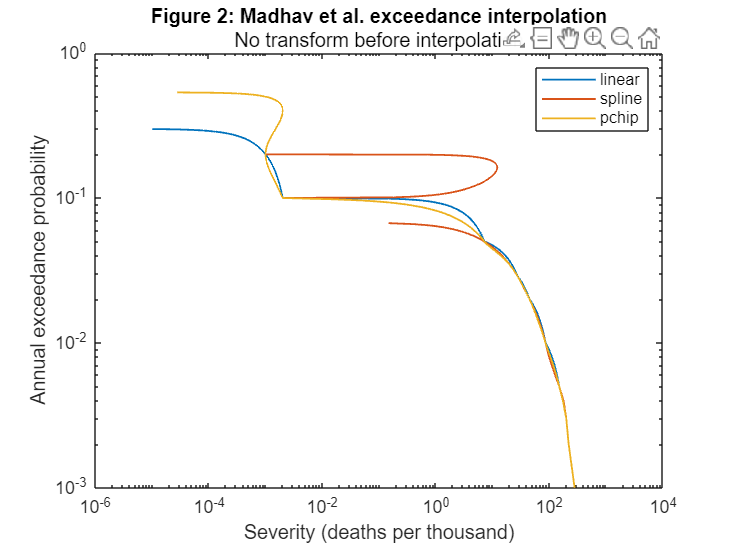

probs = 0:0.001:1;
dist_sample_points = "./pandemic-loss-modeling/exceedance_results/madhav_original.csv";
linear = load_arrival_dist(dist_sample_points, "linear", false);
spline = load_arrival_dist(dist_sample_points, "spline", false);
pchip = load_arrival_dist(dist_sample_points, "pchip", false);

Ys = [linear.get_severity(probs); 
      spline.get_severity(probs);
      pchip.get_severity(probs)];

loglog(Ys, probs, LineWidth=1);
title("Figure 2: Madhav et al. exceedance interpolation");
subtitle("No transform before interpolation");
xlabel("Severity (deaths per thousand)");
ylabel("Annual exceedance probability");
legend("linear", "spline", "pchip");
saveas(gcf, "output/figures/madhav_interpolation_no_log.jpg")

% Get the screening probability from the Madhav distribution.
linear = load_arrival_dist(dist_sample_points, "linear", true);
empirical_dist.get_severity_rank(4.59)

ans = 0.9481